# s_oeBloodFluorophoreTongueSrch700 

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 510:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:50;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

**Our winners so far**

- fluorophoreNames = 

- {'collagen1-smooth','KeratinWuQu','FADWuQu','PorphyrinBjurshammar','chlorophyllA-7'}

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = ...
    {'collagen1-smooth','KeratinWuQu','FADWuQu','PorphyrinBjurshammar','chlorophyllA-7'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 13.00
OD across subjects for 405/415nm 14.00
OD across subjects for 405/415nm 13.00
OD across subjects for 405/415nm 14.00


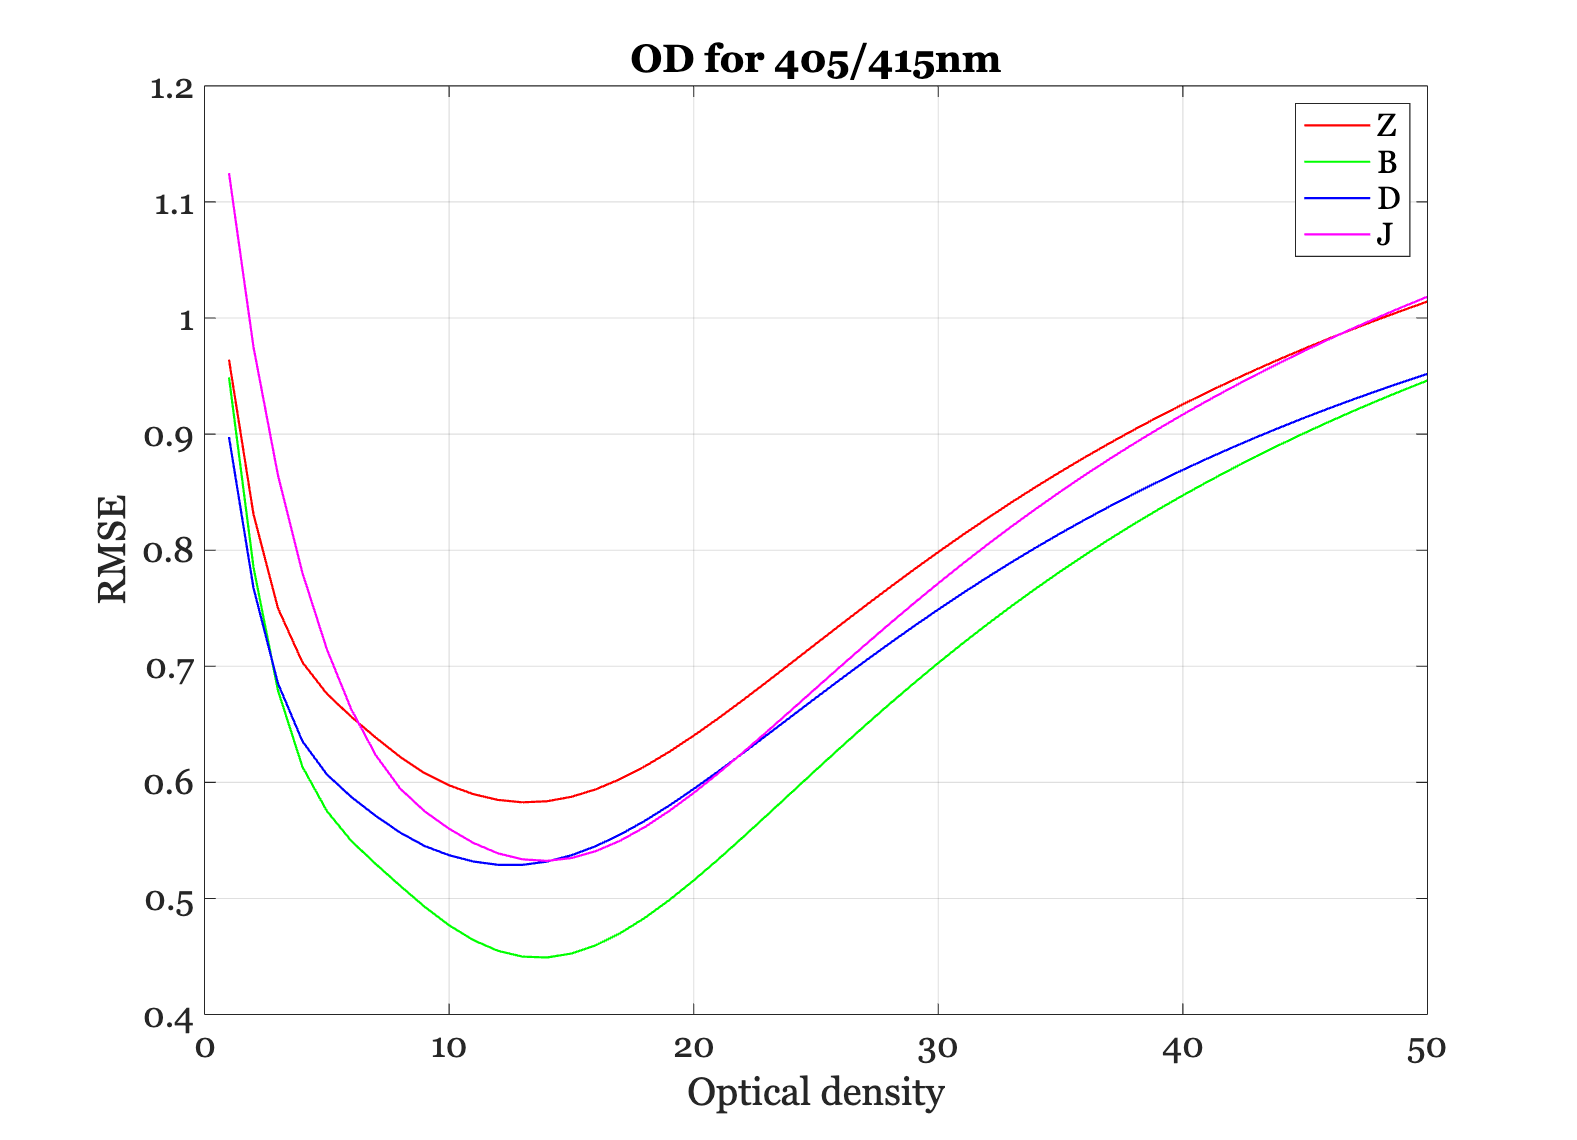


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

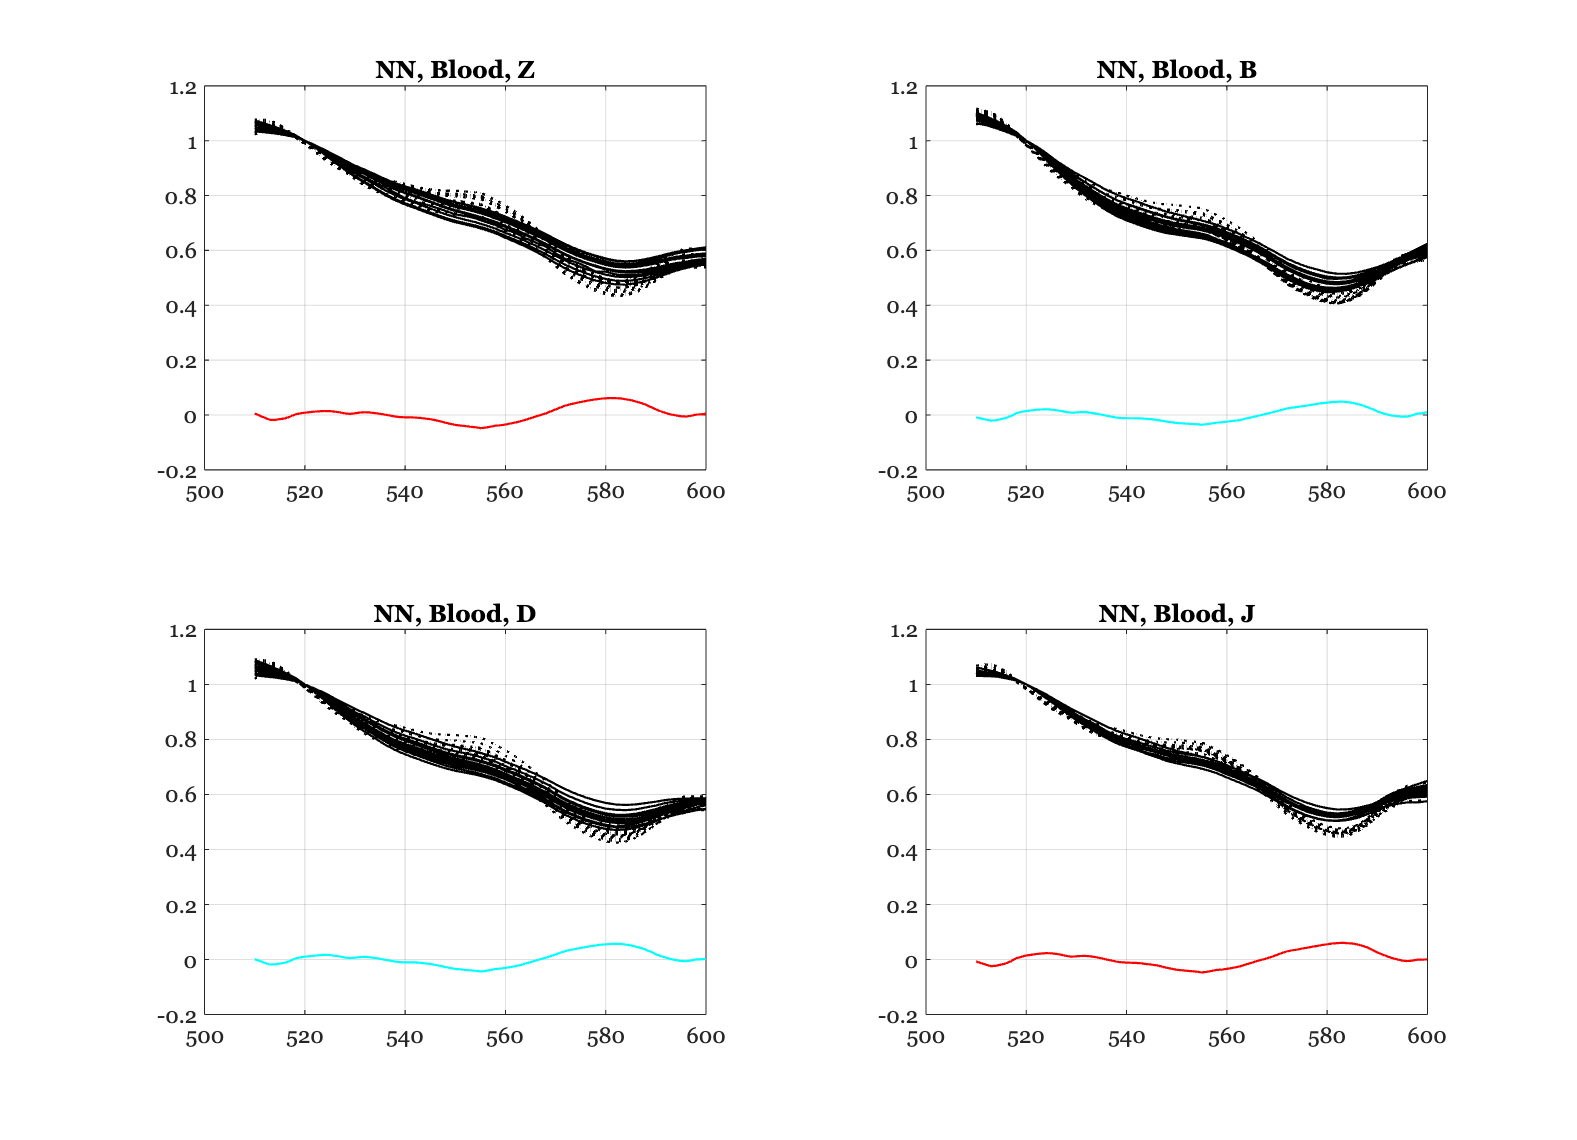

Subject Z
   10.3218   10.5950   10.4425   10.5638   12.1787   11.2377   11.9282   10.7278   11.3690   11.0282   12.1759   10.4663    9.9309   10.2424   10.2092
    1.1956    1.0544    0.9493    1.2932    0.2835    0.6178    0.3182    0.8562    0.5250    0.6195    0.3765    1.3703    0.9910    0.9323    0.9375
    0.5893    0.6187    0.6482    0.5589    0.7704    0.7084    0.7679    0.6618    0.7296    0.7130    0.7469    0.5401    0.6468    0.6534    0.6526
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

Subject B
   13.6660   12.3075   12.9855   14.5942   13.3004   13.3313   12.5877   14.3050   13.0243   13.2490   12.3892   12.8359   12.2039   13.0129
    1.1549    0.9203    0.9853    1.3322    1.3885    1.4968    1.5810    1.3091   

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

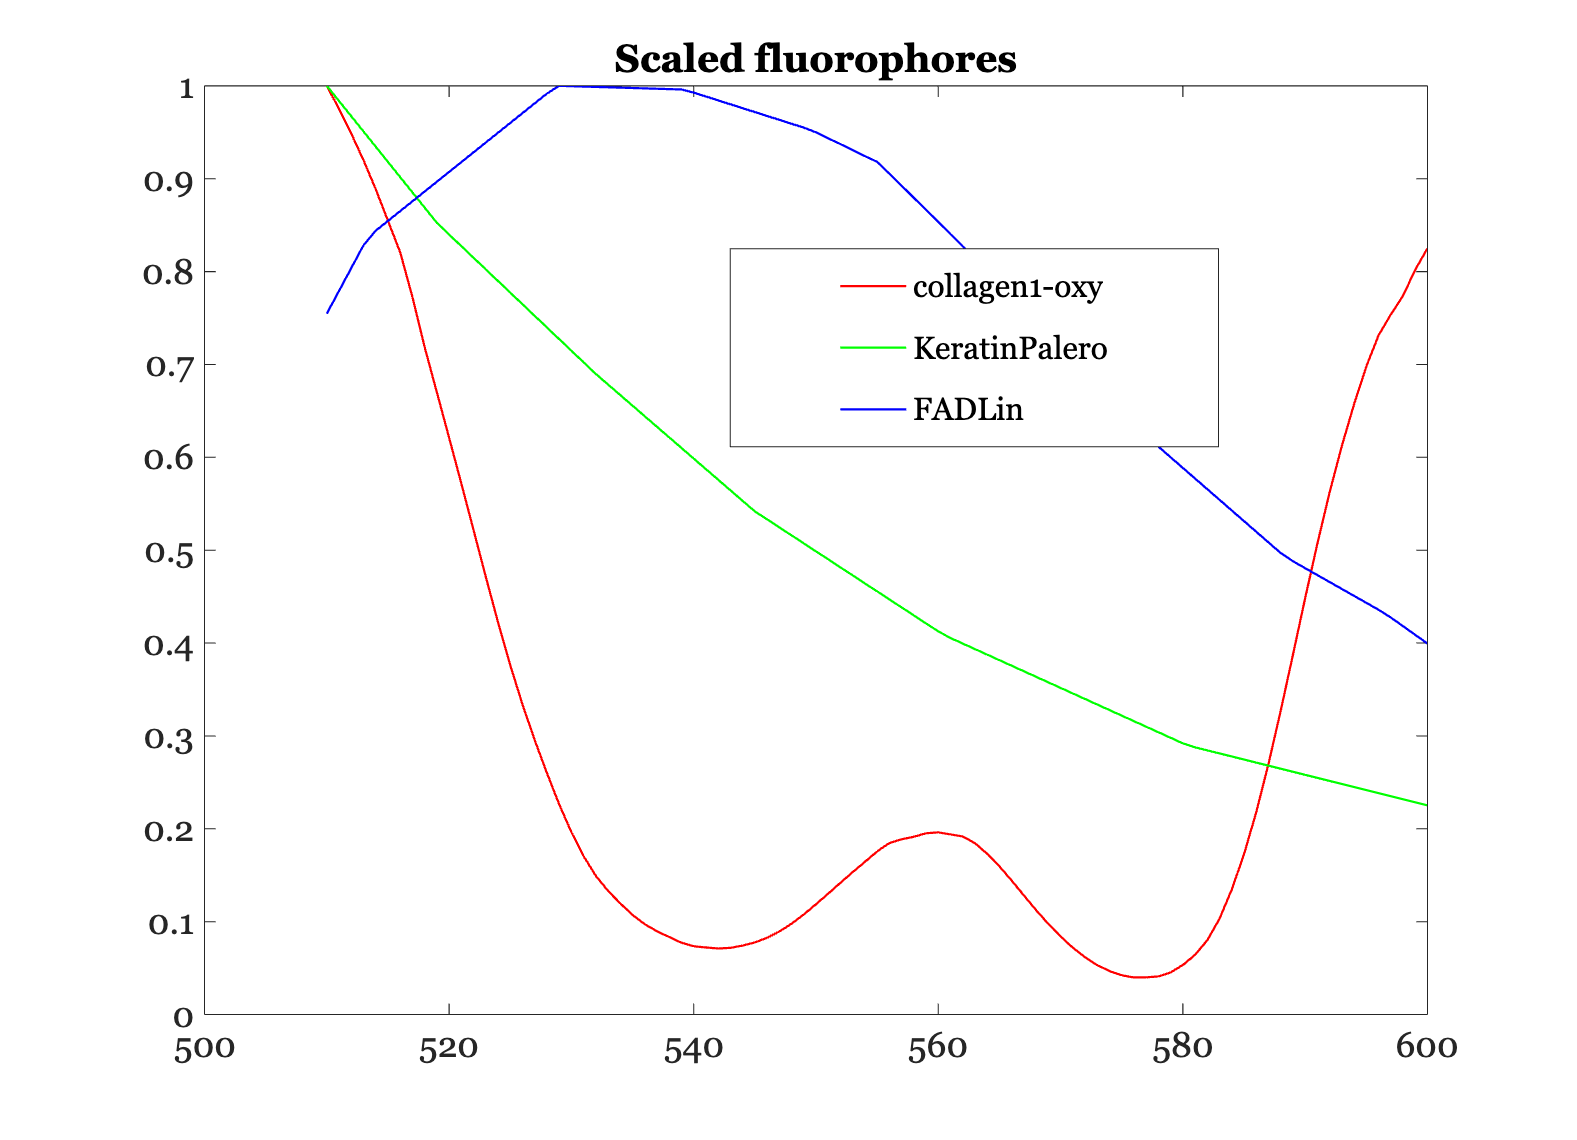


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

legend(["collagen1-oxy", "KeratinPalero", "FADLin"], "Position", [0.4630 0.6080 0.3095, 0.1743])


disp(rmse); 

    1.0846    0.8252    0.9703    1.0821



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 16.00
OD across subjects for 405/415nm 15.00
OD across subjects for 405/415nm 14.00
OD across subjects for 405/415nm 14.00


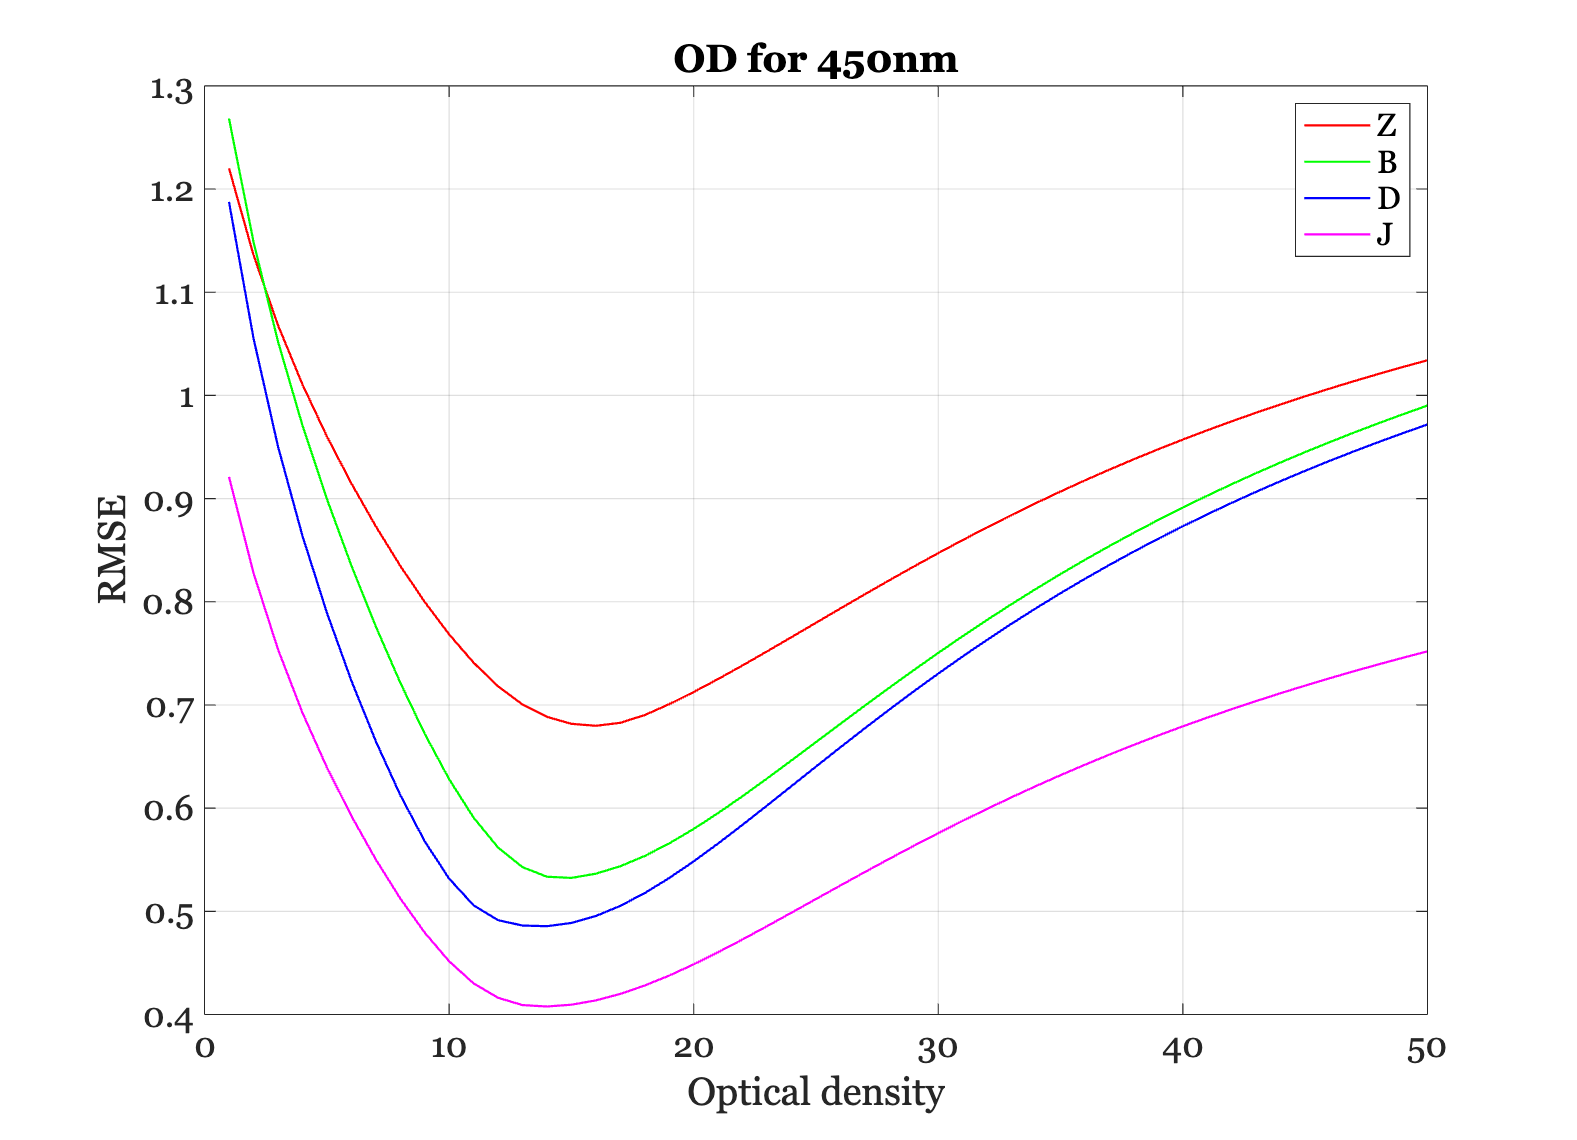



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

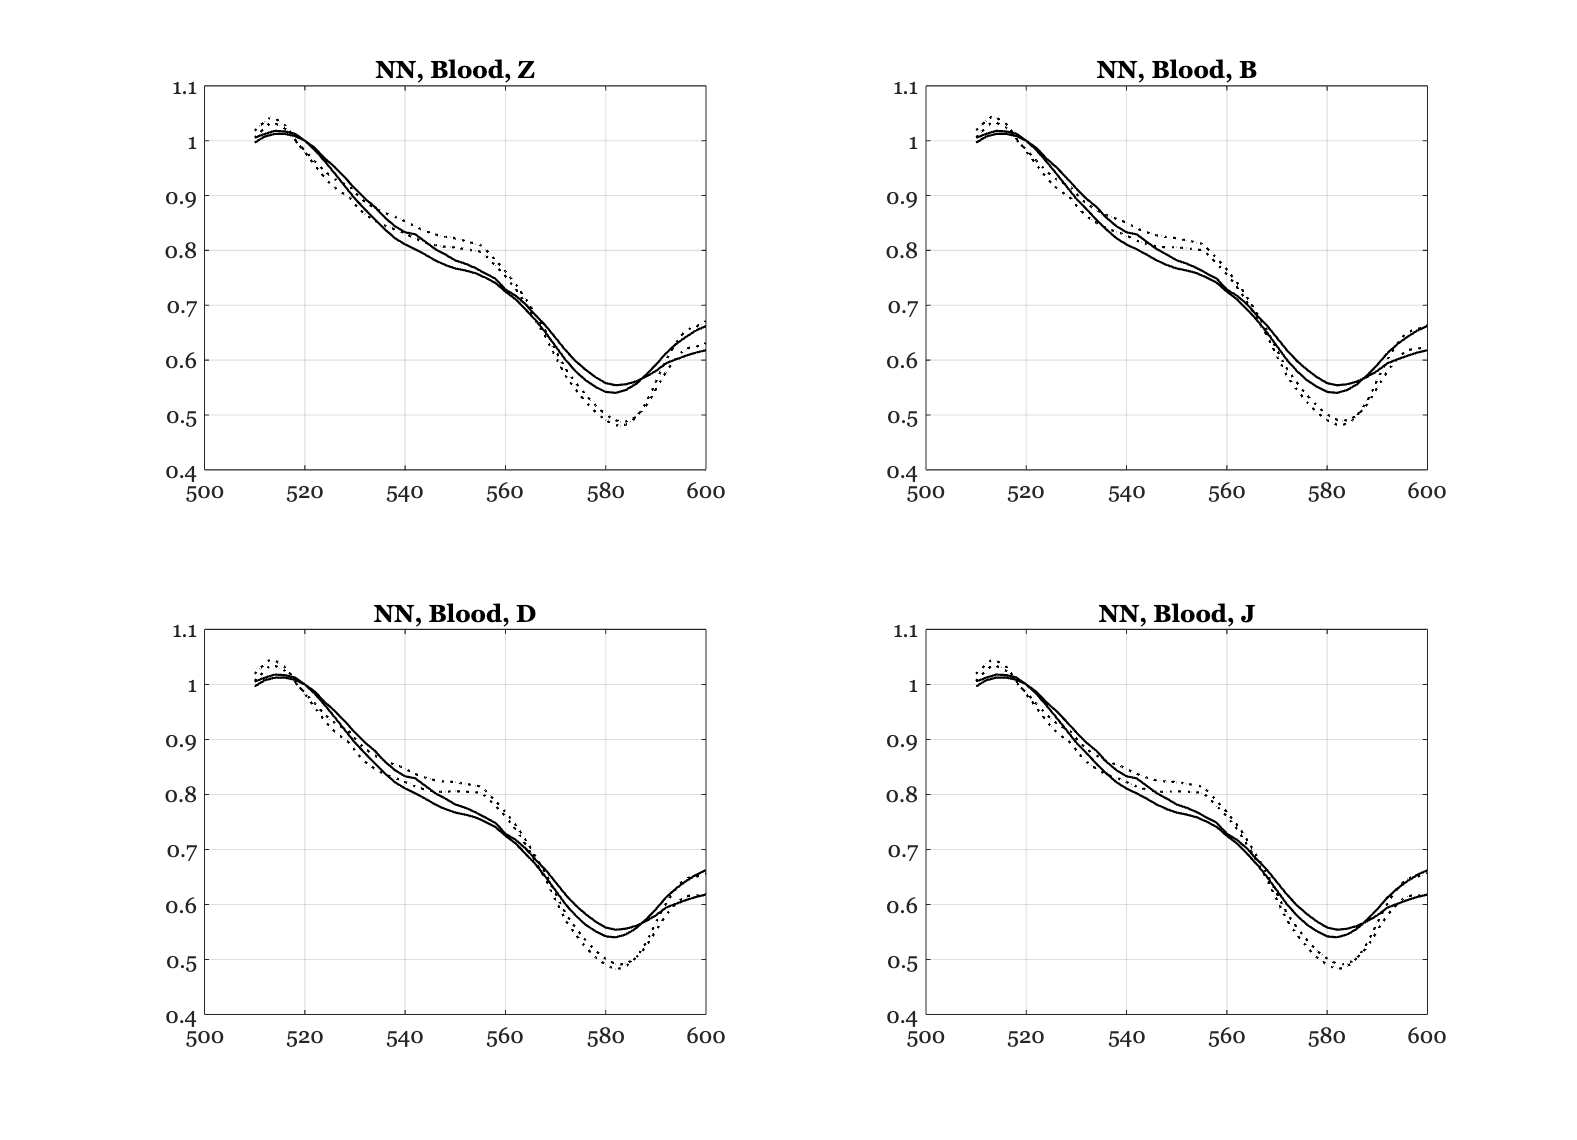

Subject Z
   15.5299   13.2817
    0.2893    0.4310
    0.7718    0.7756
         0         0
         0         0

Subject B
   15.1376   12.9504
    0.1744    0.3322
    0.7810    0.7835
         0         0
         0         0

Subject D
   14.7567   12.6286
    0.0545    0.2291
    0.7898    0.7910
         0         0
         0         0

Subject J
   14.7567   12.6286
    0.0545    0.2291
    0.7898    0.7910
         0         0
         0         0



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end